# **RRA**

# **Lab 1 (Parteneriat cu laburile scrise de PETrascu)**

clear
close all
clc

s = tf('s');

disp('H este');

H este


H = 1/(s+1) * ones(2,2)


H =
 
  From input 1 to output...
         1
   1:  -----
       s + 1
 
         1
   2:  -----
       s + 1
 
  From input 2 to output...
         1
   1:  -----
       s + 1
 
         1
   2:  -----
       s + 1
 
Continuous-time transfer function.



disp('H in state-space');

H in state-space


H_ss = ss(H)


H_ss =
 
  A = 
       x1  x2
   x1  -1   0
   x2   0  -1
 
  B = 
       u1  u2
   x1   2   0
   x2   0   2
 
  C = 
        x1   x2
   y1  0.5  0.5
   y2  0.5  0.5
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


Acum verificam controlabilitatea si observabilitatea lui H. Avem 2 metode

- Folosind matricile $P_c \;\textrm{si}\;P_o$ de ctrb respectiv de obsv

Pc = ctrb(H_ss.A,H_ss.B);

disp('Sistem controlabil?');

Sistem controlabil?


disp(rank(Pc));

     2




Po = obsv(H_ss.A,H_ss.C);

disp('Sistem observabil?');

Sistem observabil?


disp(rank(Po));

     1



        2.  Folosind criteriul PBH. Putem manual

disp(eig(H_ss.A))

    -1
    -1



disp('PBH la ctrb');

PBH la ctrb


disp(rank([-eye(size(H_ss.A)) - H_ss.A H_ss.B]))

     2



disp('PBH la obsv');

PBH la obsv


disp(rank([-eye(size(H_ss.A)) - H_ss.A ; H_ss.C]));

     1



Sau mai smecher putem gasi unde pica rangul lui $\left\lbrack s*I-A\;B\right\rbrack \;\textrm{si}\;\left\lbrack \begin{array}{c}
\textrm{sI}-A\\
C
\end{array}\right\rbrack$

help tzero

 tzero - Invariant zeros of linear system
    This MATLAB function returns the invariant zeros of MIMO dynamic system,
    sys.

    Syntax
      z = tzero(sys)
      z = tzero(A,B,C,D,E)
      z = tzero(___,tol)
      [z,nrank] = tzero(___)

    Input Arguments
      sys - MIMO dynamic system
        dynamic system model
      A,B,C,D,E - State-space matrices
        matrices
      tol - Relative tolerance controlling rank decisions
        eps^(3/4) (default) | positive scalar

    Output Arguments
      


% Aici se observa ca este gol, deci nu pica rangul matricii de ctrb
tzero (H_ss.A, H_ss.B, [], [])


ans =

  0×1 empty double column vector




% Aici vedem ca pica in -1 rangul matricii de obsv
tzero (H_ss.A, [], H_ss.C, [])

ans = -1.0000

% Acum vine intrebarea: este sistemul detectabil? Da, este

% Cum se afla stabil numeric realizarea minimala a lui H
H_ss_min = ss ( H_ss, 'min')


H_ss_min =
 
  A = 
       x1
   x1  -1
 
  B = 
          u1     u2
   x1  1.414  1.414
 
  C = 
           x1
   y1  0.7071
   y2  0.7071
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


## Cum calculam polii si zerourile ignorand forma Smith McMillan

#### Ok, ce este forma Smith-McMillan?

Mai intai sa definim o matrice de transfer (ca exemplu)$H=\left\lbrack \begin{array}{cc}
\frac{s-1}{s+1} & 0\\
0 & \frac{\left(s-1\right)\left(s+2\right)}{{\left(s+1\right)}^2 }
\end{array}\right\rbrack =\left\lbrace \begin{array}{l}
0,\textrm{daca}\;s=1\\
1,\textrm{daca}\;s=-1\\
\textrm{nedeterminat},\textrm{daca}\;s=-1\\
2\;\textrm{in}\;\textrm{rest}
\end{array}\right.$

Spunem ca **rangul normal la matricii H **este rangul maxim al lui $H\left(s\right),\forall \;s\in \mathbb{C}$. De exemplu,$\left\lbrace \begin{array}{l}
\textrm{In}\;\textrm{acest}\;\textrm{caz},\textrm{rangul}\;\textrm{normal}\;\textrm{este}\;2\;,\textrm{normal}\;\textrm{rank}\left(s*I-A\right)=2\\
\textrm{Pentru}\;H\in {\mathbb{R}}^{\textrm{nxn}} ,\textrm{normal}\;\textrm{rank}\left(s*I-A\right)=n
\end{array}\right.$. Pentru toate, cu excepția unui număr finit de $s\in \mathbb{C}$, putem avea $\textrm{rank}\;H\left(s\right)=\textrm{normal}\;\textrm{rank}\;H\left(s\right)$ deoarece determinantul oricărui minor al lui A, care este o funcție rațională, trebuie fie să se anuleze identic, fie să se anuleze doar pentru un număr finit de $s\in \mathbb{C}$

#### Teorema 1

O matrice patratica polinomiala $U\in \mathbb{R}{\left\lbrack s\right\rbrack }^{\textrm{nxn}}$ este numita **unimodulara **$\Leftrightarrow \det \left(U\right)=c,c\in \mathbb{R}-\left\lbrace 0\right\rbrace$

#### De ce:

Notatia este menita sa indice faptul ca $\det \left(U\right)$ **este o polinomiala**. Cand scriem $\det \left(U\left(s\right)\right)$, inseamna ca **determinantul este evaluat prima data**, inainte de evaluarea lui U la un anumit s. Asta inseamna, de exemplu

$\det \;\left\lbrack \begin{array}{cc}
\frac{1}{s} & 0\\
0 & s
\end{array}\right\rbrack =1$ si nu este nedefinit in $s=0$

Presupunem ca U si V sunt matrici** unimodulare**.

$\textrm{rank}\;\textrm{UDV}=\textrm{rank}\;D$. Se poate observa ca inmultirea matricii D cu **matrici unimodulare ***NU SCHIMBA RANGUL*

#### Ok, acum sa trercem la ce ne trebuie noua:

$H\left(s\right)=U\left(s\right)\;D\left(s\right)\;V\left(s\right)$, unde U si V am zis mai sus ca cunt matrici polinomiale unimodulare **SI NU SUNT UNICE**.

Cine este **acel D** acum? El are o forma mai speciala

$D=\left\lbrack \begin{array}{cccccccc}
\frac{\epsilon_1 \left(s\right)}{\eta_1 \left(s\right)} &  &  &  &  &  &  & \\
 & \frac{\epsilon_2 \left(s\right)}{\eta_2 \left(s\right)} &  &  &  &  &  & \\
 &  & \ddots  &  &  &  &  & \\
 &  &  & \frac{\epsilon_r \left(s\right)}{\eta_r \left(s\right)} &  &  &  & \\
 &  &  &  & 0 &  &  & \\
 &  &  &  &  & 0 &  & \\
 &  &  &  &  &  & \ddots  & \\
 &  &  &  &  &  &  & 0
\end{array}\right\rbrack$, unde $\epsilon_i \;\textrm{si}\;\eta_i \;\textrm{sunt}\left\lbrace \begin{array}{l}
\textrm{coprime}\;\textrm{intre}\;\textrm{ele}\\
\textrm{sunt}\;\textrm{polinoame}\;\textrm{monice}\;\left(1*s^n +a_{n-1} s^{n-1} \cdots a_0 \right)\\
\epsilon_i |\epsilon_{i+1} ,\forall i\in \left\lbrack 1,r-1\right\rbrack \\
\eta_{i+1} |\eta_i ,\forall i\in \left\lbrack 1,r-1\right\rbrack \\
\textrm{nu}\;\textrm{sunt}\;\textrm{unic}\;\textrm{identic}\;0,\forall i\in \left\lbrack 1,r\right\rbrack 
\end{array}\right.$

**Polii finiti ai lui **$H\left(s\right)$ sunt radacinile polinoamelor $\eta_i$, iar gradee partiale ale acestor poli = gradele partiale ca radacini ale polinoamelor $\eta_i$

**Zerourile finite ai lui **$H\left(s\right)$ sunt radacinile polinoamelor $\epsilon_i$, iar gradee partiale ale acestor zerouri = gradele partiale ca radacini ale polinoamelor $\epsilon_i$

Acum sa trecem la oile noastre

clear
close all
clc

s = tf('s');

H = [1/(s+1) 1/(s+2);
     1/(s+3) 1/(s+4)]


H =
 
  From input 1 to output...
         1
   1:  -----
       s + 1
 
         1
   2:  -----
       s + 3
 
  From input 2 to output...
         1
   1:  -----
       s + 2
 
         1
   2:  -----
       s + 4
 
Continuous-time transfer function.



H_ss_min = ss(H,'min')


H_ss_min =
 
  A = 
       x1  x2  x3  x4
   x1  -1   0   0   0
   x2   0  -3   0   0
   x3   0   0  -2   0
   x4   0   0   0  -4
 
  B = 
       u1  u2
   x1   1   0
   x2   1   0
   x3   0   1
   x4   0   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   1   0
   y2   0   1   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


### Pentru un sistem minimal, polii lui H sunt valorile proprii ale lui A

In acest sens, ne uitam la forma Jordan $A={\textrm{TJT}}^{-1}$, unde **J** este **matrice Jordan**

$J=\left\lbrack \begin{array}{cccccccc}
\lambda_1  & 1 &  &  &  &  &  & \\
 & \lambda_2  & 1 &  &  &  &  & \\
 &  & \lambda_3  & 1 &  &  &  & \\
 &  &  & \lambda_4  & 1 &  &  & \\
 &  &  &  & \lambda_5  & \ddots  &  & \\
 &  &  &  &  & \ddots  & 1 & \\
 &  &  &  &  &  & \lambda_{j-1}  & 1\\
 &  &  &  &  &  &  & \lambda_j 
\end{array}\right\rbrack$, unde $\Lambda \left(A\right)=\left\lbrace \lambda_1 ,\lambda_2 ,\cdots ,\lambda_j \right\rbrace$, unde fiecare valoare proprie are multiplicitati partiale $\left(n_{\textrm{i1}} ,n_{\textrm{i2}} ,\cdots ,n_{\textrm{ij}} \right)$

$\chi \left(\lambda \right)=\det \left(\lambda I-A\right)$ si se numeste **polinomul caracteristic**

$\chi^{\prime } \left(\lambda \right)\to$aici $\lambda$ apar la la puterea marimii **celui mai mare Bloc Jordan ales**

Pentru blocul Jordan $J=\left\lbrack \begin{array}{ccccc}
3 & 0 &  &  & \\
 & 2 & 0 &  & \\
 &  & 2 & 1 & \\
 &  &  & 2 & 0\\
 &  &  &  & 2
\end{array}\right\rbrack$ 

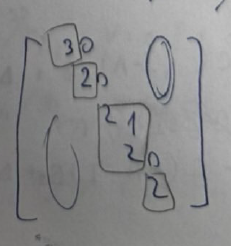

si sa presupunem ca avem asa: $\left\lbrace \begin{array}{l}
\textrm{mp}\left(3\right)=1\\
\textrm{mp}\left(2\right)=\left\lbrace 1,1,2\right\rbrace \to \textrm{acesta}\;\textrm{este}\;\textrm{un}\;\textrm{multiset}
\end{array}\right.$. Daca ne uitam la $\chi^{\prime } \left(2\right)$, vedem ca este 2 pt ca dimensiunea celui mai mare bloc Jordan este 2 

tzero (H_ss_min.A, H_ss_min.B, H_ss_min.C, H_ss_min.D)


ans =

  0×1 empty double column vector



% In acest fel primim zerourile finite

- **Suma gradelor partiale ale tuturor polilor (finiti + infiniti) se numeste gradul McMillan al rationalei**

- **Cand rationala e proprie, gradul McMillan coincide cu dimensiunea realizarii minimale **(De ce: deoarece nu avem poli infiniti si doar adunam marimile blocurilor Jordan din minimala)

Fie matricile $\left\lbrace \begin{array}{l}
A_z =\left\lbrack \begin{array}{cc}
A & B\\
C & D
\end{array}\right\rbrack \\
E_z =\left\lbrack \begin{array}{cc}
I_n  & 0\\
0 & 0
\end{array}\right\rbrack 
\end{array}\Rightarrow A_z -s*E_z =\left\lbrack \begin{array}{cc}
A-{\textrm{sI}}_n  & B\\
C & D
\end{array}\right\rbrack \right.$, unde

$\begin{array}{l}
A_z -{\textrm{sE}}_z =\textrm{fascicul}\;\textrm{de}\;\textrm{zerouri}\;/\;\textrm{sistemal}\;\textrm{lui}\;H\\
A-{\textrm{sI}}_n =\textrm{fascicul}\;\textrm{de}\;\textrm{poli}\;\textrm{al}\;\textrm{lui}\;H
\end{array}$. In acest sens, $Z_f =\Lambda_f \left(A_z -s*E_z \right)$, unde $\Lambda_f$ sunt **Valori Proprii Generalizate (V.P.Gen / V.P.G), **iar gradele partiale sunt multiplicitati partiale ale **Valorilor Proprii Generalizate (V.P.Gen / V.P.G) **ale lui $A_z -{\textrm{sE}}_z$

Zerourile infinite $Z_{\infty } \left\lbrace H\right\rbrace$se mapeaza peste **V.P.G** infinite $\Lambda_{\infty } \left(A_z -s*E_z \right)$ in sensul in care *gradele partiale sunt egale cu multiplicitatile partiale ****CU V.P.G MINUS 1***

#### Din fericire, putem scapa de uratenia asta. Cum mai exact? Inlocuim $s\to \frac{1}{s}$. Facem asta pentru a nu ne uita la infinit si a ne uita spre 0. Este mult mai ok de vazut

## Explicatie V.P.G $\infty$


$$T\left(\textrm{sI}-A\right)T^{-1} =\textrm{sI}-J,\textrm{unde}\;J\;\textrm{este}\;\textrm{ma}\textrm{trice}\;\textrm{Jordan}$$


$\textrm{sE}-A$** poate sau nu fi matrice patrat**

### Aici avem mai multe cazuri:

#### Caz1: Cand $\textrm{sE}-A\;\textrm{este}\;\textrm{patratic}\;\textrm{si}\;\det \left(\textrm{sE}-A\right)\not= 0$. In acwest caz, se numeste fascicul patrat

$\exists \;Q\;\textrm{si}\;Z$ inversabile pentru care $Q\left(\textrm{sE}-A\right)Z=\left\lbrack \begin{array}{cc}
\textrm{sI}-J & 0\\
0 & \textrm{sN}-I
\end{array}\right\rbrack$care se numeste **forma canonica Weierstrass**, iar$\left\lbrace \begin{array}{l}
I\ldotp \;\Lambda_f \left(\textrm{sE}-A\right)=\Lambda \left(J\right),\textrm{cu}\;J\;o\;\textrm{forma}\;\textrm{canonica}\;\textrm{Jordan}\\
{\textrm{II}\ldotp \;\Lambda }_{\infty } \left(\textrm{sE}-A\right)\;\textrm{esre}\;\textrm{dat}\;\textrm{de}\;\Lambda_{\infty } \left(\textrm{sN}-I\right)=\Lambda_0 \left(\textrm{sA}-E\right)=\Lambda_0 \left(\textrm{sI}-N\right)
\end{array}\right.$cu tot cu multiplicitati partiale, unde $N$este o **matrice nilpotenta in forma canonica Jordan**

Practic ce fac este sa **inversez N si I** intre ele, respectiv **E si A** intre ele pentru **a ma putea uita in zero**

#### Acum ce este aceea o matrice nilpotenta?

N este o matrice nilpotenta daca $\exists \;k\in \mathbb{N}$a.i $N^k =0_n$, unde cel mai mic k care respecta aceasta egalitate se numeste **indice de nilpotenta**

**Forma canonica Jordan pentru nilpotenta **$N_j =\left\lbrack \begin{array}{cccccccc}
0 &  &  &  &  &  &  & \\
 & 0 &  &  &  &  &  & \\
 &  & 0 & 1 &  &  &  & \\
 &  &  & 0 & 1 & 0 &  & \\
 &  &  &  & 0 & 1 &  & \\
 &  &  &  &  & 0 &  & \\
 &  &  &  &  &  & 0 & \\
 &  &  &  &  &  &  & \ddots 
\end{array}\right\rbrack$

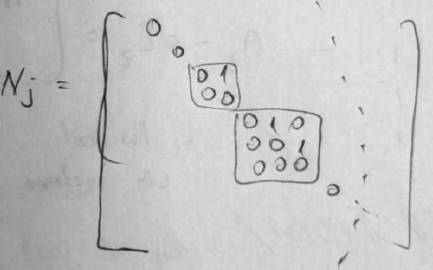 indicele de nilpotenta este marimea celui mai mare bloc Jordan

Acum va urma o explicatie la ${\textrm{II}\ldotp \;\Lambda }_{\infty } \left(\textrm{sE}-A\right)\;\textrm{esre}\;\textrm{dat}\;\textrm{de}\;\Lambda_{\infty } \left(\textrm{sN}-I\right)=\Lambda_0 \left(\textrm{sA}-E\right)=\Lambda_0 \left(\textrm{sI}-N\right)$


$$\left(\textrm{sN}-I\right)=\left\lbrack \begin{array}{cccccccc}
-1 &  &  &  &  &  &  & \\
 & -1 & s &  &  &  &  & \\
 &  & -1 & s & 0 &  &  & \\
 &  &  & -1 & s &  &  & \\
 &  &  &  & -1 &  &  & \\
 &  &  &  &  & -1 &  & \\
 &  &  &  &  &  & -1 & \\
 &  &  &  &  &  &  & \ddots 
\end{array}\right\rbrack \leftrightarrow \left(\textrm{sI}-N\right)=\left\lbrack \begin{array}{cccccccc}
s &  &  &  &  &  &  & \\
 & s & 1 &  &  &  &  & \\
 &  & s & 1 & 0 &  &  & \\
 &  &  & s & 1 &  &  & \\
 &  &  &  & s &  &  & \\
 &  &  &  &  & s &  & \\
 &  &  &  &  &  & s & \\
 &  &  &  &  &  &  & \ddots 
\end{array}\right\rbrack$$


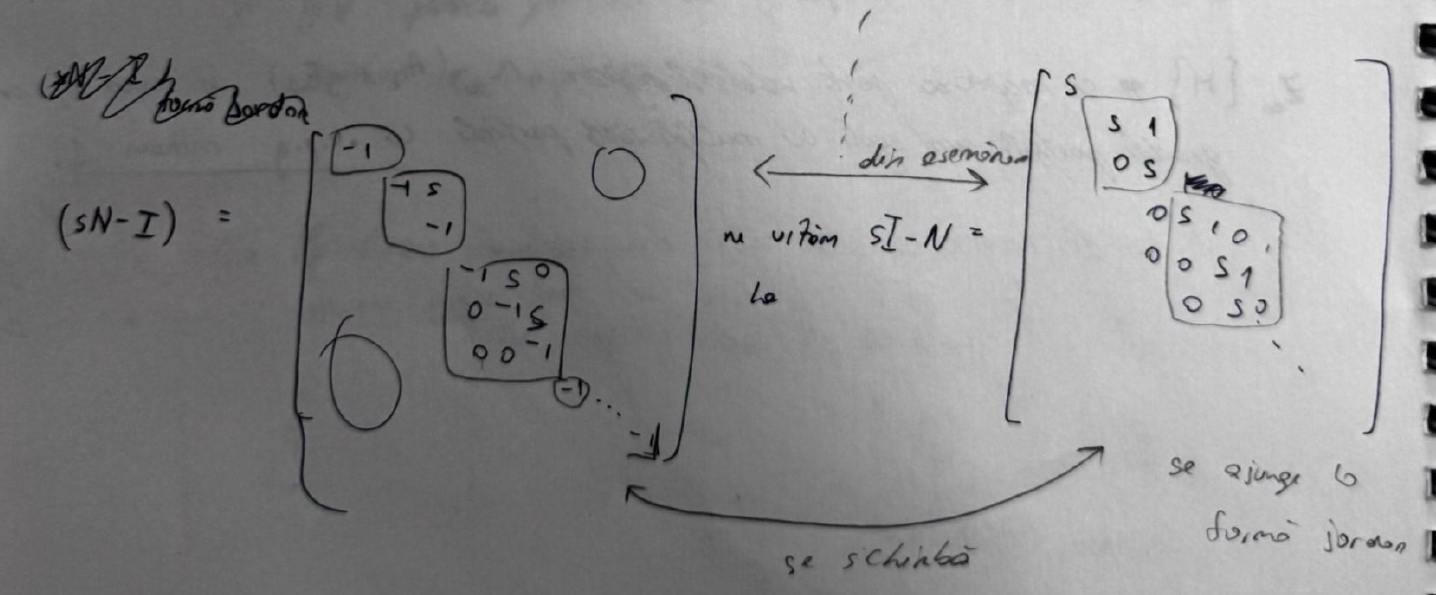

#### Caz 2: $\textrm{sE}-A$ nu este partat sau este patrat dar $\det \left(\textrm{sE}-A\right)=0$. Aici se numeste fascicul singular

Fie Q si R invariante a.i $Q\left(\textrm{sE}-A\right)R=\left\lbrack \begin{array}{cccc}
{\textrm{sE}}_r -A_r  &  &  & \\
 & \textrm{sI}-J &  & \\
 &  & \textrm{sN}-I & \\
 &  &  & {\textrm{sE}}_e -A_e 
\end{array}\right\rbrack$ este **forma canonica Kronecker**, unde $\left\lbrace \begin{array}{l}
{\textrm{sE}}_r -A_r \;\textrm{are}\;\textrm{rang}\;\textrm{intreg}\;\textrm{pe}\;\textrm{linii}\\
\textrm{sI}-J\;\textrm{si}\;\textrm{sN}-I\;\textrm{sunt}\;\textrm{valori}\;\textrm{proprii}\;\textrm{finite}\;\textrm{si}\;\textrm{infinite}\\
{\textrm{sE}}_e -A_e \;\textrm{are}\;\textrm{rang}\;\textrm{intreg}\;\textrm{pe}\;\textrm{coloane}\;\textrm{si}\;\textrm{este}\;\textrm{de}\;\textrm{forma}\;\textrm{Kronecker}
\end{array}\right.$

eig ([H_ss_min.A, H_ss_min.B; H_ss_min.C, H_ss_min.D], ...
    blkdiag(eye(4), zeros(2)))

ans =   -Inf
  -Inf
   Inf
  -Inf
  -Inf
   Inf



% problema, trebuie sa facem pe H_tilda ca ne da doar inf, si nu stim
% deloc multiplicitatile partiale
% ne-a dat 6 infinituri

Aici facem $\tilde{H\left(s\right)} =H\left(\frac{1}{s}\right)$

Acum calculam zerourile infinite cu s = 1/s

Htilde = [s/(s+1) s/(2*s+1);
          s/(3*s+1) s/(4*s+1)]


Htilde =
 
  From input 1 to output...
         s
   1:  -----
       s + 1
 
          s
   2:  -------
       3 s + 1
 
  From input 2 to output...
          s
   1:  -------
       2 s + 1
 
          s
   2:  -------
       4 s + 1
 
Continuous-time transfer function.



Htilde_min = ss(Htilde, 'min')


Htilde_min =
 
  A = 
            x1       x2       x3       x4
   x1       -1        0        0        0
   x2        0  -0.3333        0        0
   x3        0        0     -0.5        0
   x4        0        0        0    -0.25
 
  B = 
         u1    u2
   x1     1     0
   x2  0.25     0
   x3     0   0.5
   x4     0  0.25
 
  C = 
            x1       x2       x3       x4
   y1       -1        0     -0.5        0
   y2        0  -0.4444        0    -0.25
 
  D = 
           u1      u2
   y1       1     0.5
   y2  0.3333    0.25
 
Continuous-time state-space model.



tzero(Htilde_min)

ans = 1.0e-05 *

  -0.4073 + 0.0000i
   0.2037 + 0.3528i
   0.2037 - 0.3528i
  -0.0000 + 0.0000i


Exista 3 feluri de zerouri:

$\left\lbrace \begin{array}{l}
0\;\textrm{de}\;\textrm{transmisie}\;\left(\textrm{ale}\;\textrm{lui}\;H\left(s\right)\right),\textrm{tin}\;\textrm{de}\;H\left(s\right)\\
0\;\textrm{blocant},\;\textrm{exemplu}:H\left(\infty \right)=\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right\rbrack \\
0\;\textrm{invariant}:\textrm{tzero}\left(A-\textrm{sE},B,C,D\right);\textrm{tine}\;\textrm{de}\;A-\textrm{sE},B,C,D
\end{array}\right.$. In plus, daca realizarea este minimala, atunci 0 invariante coincid cu cele de transmisie

**0 de tranzitie sunt un subset al zerourilor invariante**